# Testing all images in DB to our dataset in DB1

clear TNM034
clear
clf
clc
clear livescript

Building dataset:
Creating image matrix
Image: db1_01.jpg 


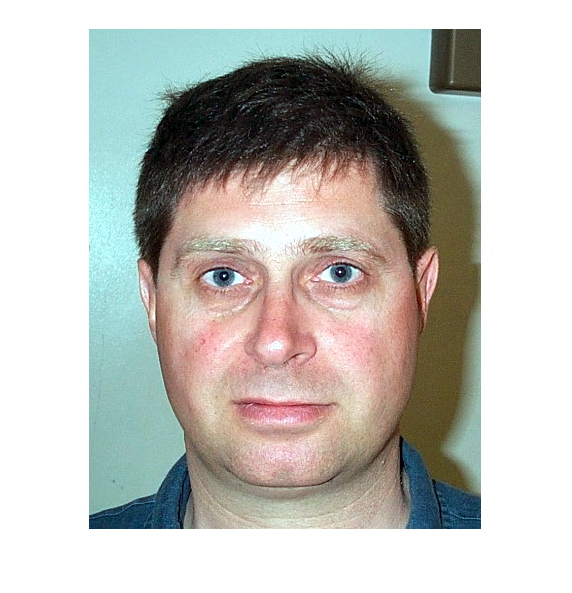

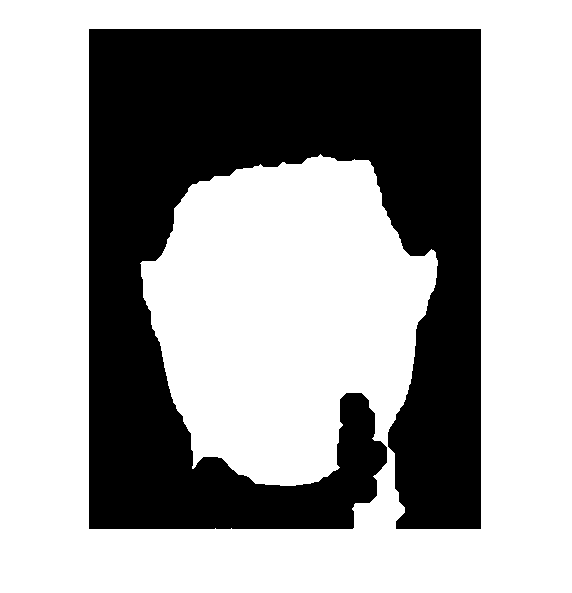

Image: db1_02.jpg 


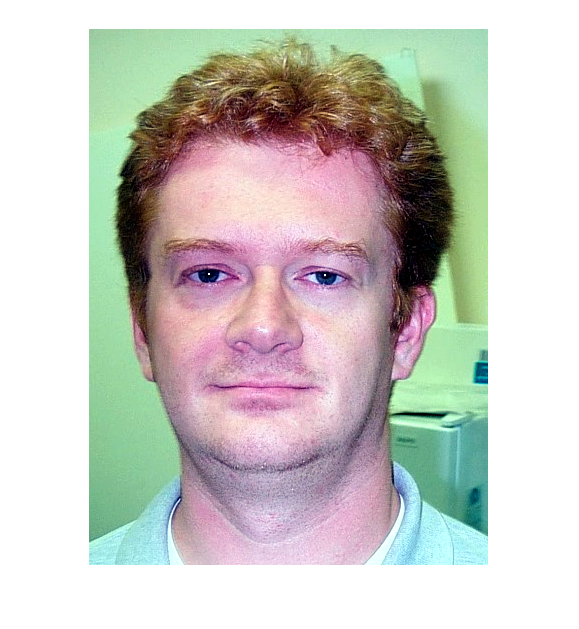

Image: db1_03.jpg 


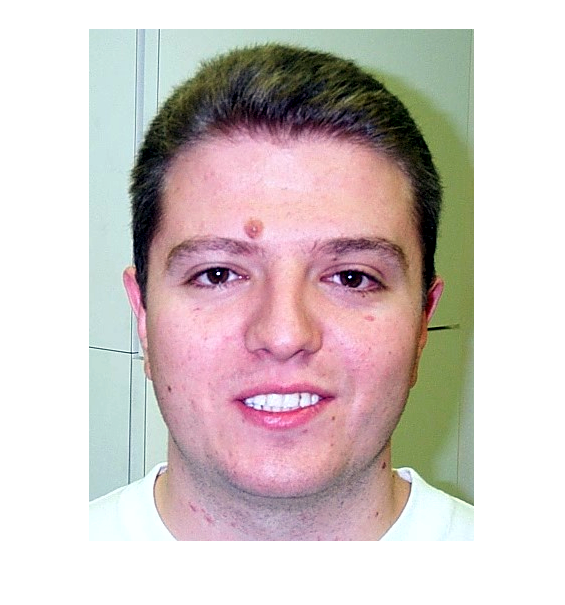

files=dir('./DB1/*.jpg');
files =  {files.name};

% Test all files in a dataset against our dataset based on DB1
for file = files
    path = './DB1/' + string(file);
    im = imread(path);
    [id,value] = TNM034(im*1.1);
    fprintf('%s, %i, %.4f \n', string(file), id, value);
end

% [id,value] = TNM034(imread('./DB1/db1_08.jpg'));
[id,value] = TNM034(1.1*imread('./DB1/db1_08.jpg'));
fprintf('%s, %i, %f \n','', id, value);

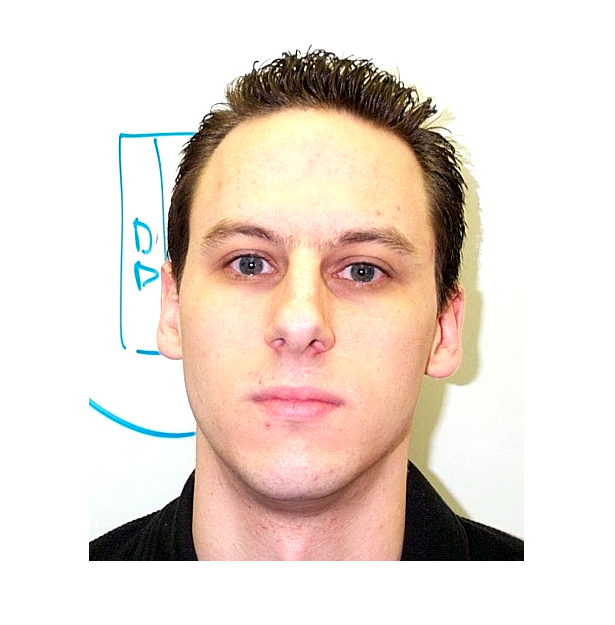

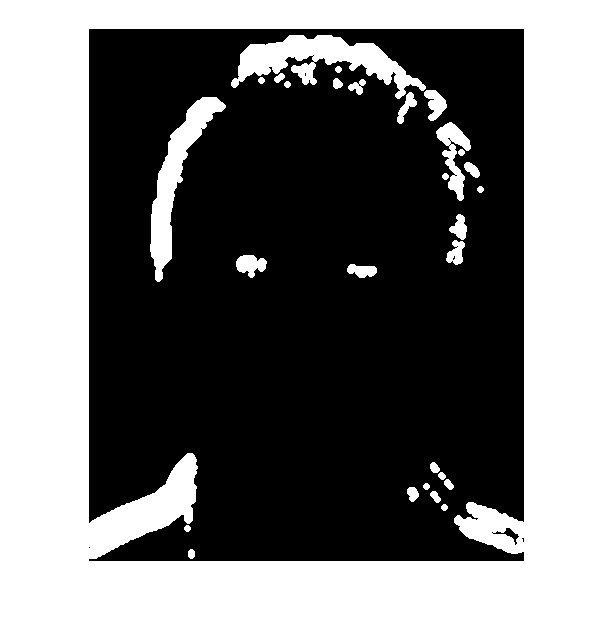

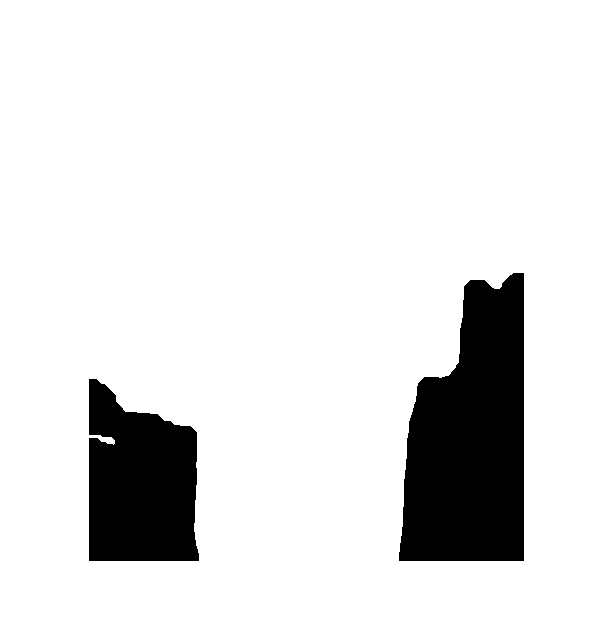

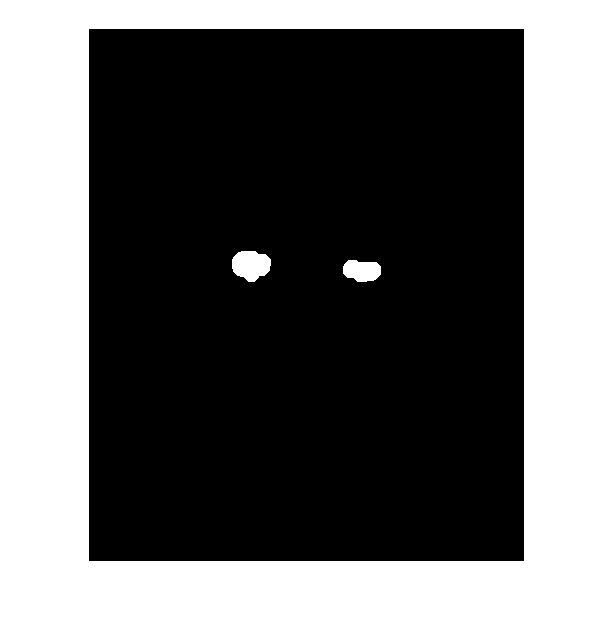

im = 200×200×3 uint8 array
im(:,:,1) =

   252   255   255   255   255   255   254   254   255   255   255   255   255   255   255   255   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255

im = imread('./DB1/db1_15.jpg');
im = cropImage(im*1.1)

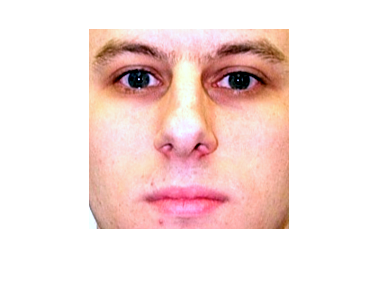

im = whitePatch(im);
im = normalizeRGBImage(im);
imshow(im)

im = faceMask(im);
imshow(im)